# RVC2: Chapter 9 - Dynamics and Control

close all
bdclose('all')
clear
clc

## 9.1 Independent joint control

## 9.1.3  Effect of link mass

mdl_twolink_sym

Iyy1 = 0

Iyy2 = 0

b1 = 0

b2 = 0

syms q1 q2 q1d q2d q1dd q2dd real
tau = twolink.rne([q1 q2], [q1d q2d], [q1dd q2dd])

$$tau = \begin{array}{l} \left(\begin{array}{cc} m_{1}\,\left(a_{1}+c_{1}\right)\,\left(a_{1}\,\mathrm{q1dd}+c_{1}\,\mathrm{q1dd}+g\,\cos\left(q_{1}\right)\right)+\sigma_{1}-a_{1}\,m_{2}\,\sin\left(q_{2}\right)\,\left(a_{2}\,{\left(\mathrm{q1d}+\mathrm{q2d}\right)}^{2}+c_{2}\,{\left(\mathrm{q1d}+\mathrm{q2d}\right)}^{2}-\sin\left(q_{2}\right)\,\left(a_{1}\,\mathrm{q1dd}+g\,\cos\left(q_{1}\right)\right)+\cos\left(q_{2}\right)\,\sigma_{3}\right)+a_{1}\,m_{2}\,\cos\left(q_{2}\right)\,\sigma_{2} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,\left(a_{2}+c_{2}\right)\,\sigma_{2}\\ \sigma_{2}=a_{2}\,\left(\mathrm{q1dd}+\mathrm{q2dd}\right)+c_{2}\,\left(\mathrm{q1dd}+\mathrm{q2dd}\right)+\cos\left(q_{2}\right)\,\left(a_{1}\,\mathrm{q1dd}+g\,\cos\left(q_{1}\right)\right)+\sin\left(q_{2}\right)\,\sigma_{3}\\ \sigma_{3}=a_{1}\,{\mathrm{q1d}}^{2}-g\,\sin\left(q_{1}\right) \end{array}$$

## 9.1.5  Modeling the robot joint

mdl_puma560

tf = p560.jointdynamics(qn);

Fast RNE: (c) Peter Corke 2002-2012



tf(2)


ans =
 
            1
  ----------------------
  0.0005797 s + 0.000817
 
Continuous-time transfer function.



## 9.1.6  Velocity control loop

vloop_test

sim('vloop_test')


Simulink.SimulationOutput:

    t: [1000×1 double]
    y: [1000×4 double]
Use get to access a variable by name.
Use getSimulationMetadata to access metadata about the simulation.



## 9.1.7  Position control loop

ploop_test

## 9.2  Rigid-body equations of motion

mdl_puma560

Q = p560.rne(qn, qz, qz)

Q =    -0.0000   31.6399    6.0351    0.0000    0.0283         0


Q = p560.rne(qn, qz, qz, 'gravity', [0 0 0])

Q =      0     0     0     0     0     0


q = jtraj(qz, qr, 10)

q =          0         0         0         0         0         0
         0    0.0181   -0.0181         0         0         0
         0    0.1200   -0.1200         0         0         0
         0    0.3297   -0.3297         0         0         0
         0    0.6231   -0.6231         0         0         0
         0    0.9477   -0.9477         0         0         0
         0    1.2411   -1.2411         0         0         0
         0    1.4508   -1.4508         0         0         0
         0    1.5527   -1.5527         0         0         0
         0    1.5708   -1.5708         0         0         0

Q = p560.rne(q, 0*q, 0*q)

Q =          0   37.4837    0.2489         0         0         0
    0.0000   37.4590    0.2489         0         0         0
   -0.0000   37.0931    0.2489    0.0000    0.0000         0
    0.0000   35.1470    0.2489   -0.0000   -0.0000         0
    0.0000   29.8883    0.2489         0         0         0
    0.0000   21.1462    0.2489   -0.0000   -0.0000         0
    0.0000   11.3341    0.2489         0         0         0
   -0.0000    3.6906    0.2489         0         0         0
    0.0000   -0.1006    0.2489         0         0         0
   -0.0000   -0.7752    0.2489         0         0         0

about(Q)

Q [double] : 10x6 (480 bytes)



Q(5,:)

ans =     0.0000   29.8883    0.2489         0         0         0


p560.rne(qn, [1 0 0 0 0 0], qz, 'gravity', [0 0 0])

ans =    30.5332    0.6280   -0.3607   -0.0003   -0.0000         0


p560.links(1).dyn

Revolute(std): theta=q, d=0, a=0, alpha=1.5708, offset=0
  m    = 0          
  r    = 0           0           0          
  I    = | 0           0           0           |
         | 0           0.35        0           |
         | 0           0           0           |
  Jm   = 0.0002     
  Bm   = 0.00148    
  Tc   = 0.395      (+) -0.435     (-)
  G    = -62.61     
  qlim = -2.792527 to 2.792527


## 9.2.1  Gravity term

gravload = p560.gravload(qn)

gravload =    -0.0000   31.6399    6.0351    0.0000    0.0283         0


p560.gravity = p560.gravity/6;

p560.gravload(qn)

ans =     0.0000    5.2733    1.0059    0.0000    0.0047         0


p560.base = SE3.Rx(pi);
p560.gravload(qn)

ans =     0.0000    5.2733    1.0059    0.0000    0.0047         0


mdl_puma560

Q = p560.gravload(qs)

Q =    -0.0000   46.0069    8.7722    0.0000    0.0283         0


Q = p560.gravload(qr)

Q =          0   -0.7752    0.2489         0         0         0

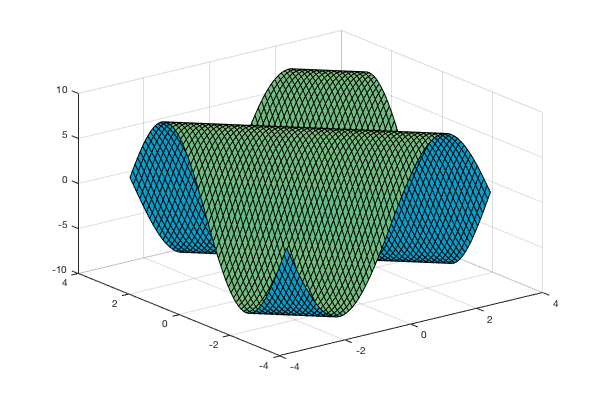


[Q2,Q3] = meshgrid(-pi:0.1:pi, -pi:0.1:pi);
for i=1:numcols(Q2),
    for j=1:numcols(Q3);
        g = p560.gravload([0 Q2(i,j) Q3(i,j) 0 0 0]);
        g2(i,j) = g(2);
        g3(i,j) = g(3);
    end
end
surfl (Q2, Q3, g2); surfl (Q2, Q3, g3);

## 9.2.2  Inertia matrix

M = p560.inertia(qn)

M =     3.6594   -0.4044    0.1006   -0.0025    0.0000   -0.0000
   -0.4044    4.4137    0.3509    0.0000    0.0024    0.0000
    0.1006    0.3509    0.9378    0.0000    0.0015    0.0000
   -0.0025    0.0000    0.0000    0.1925    0.0000    0.0000
    0.0000    0.0024    0.0015    0.0000    0.1713    0.0000
   -0.0000    0.0000    0.0000    0.0000    0.0000    0.1941

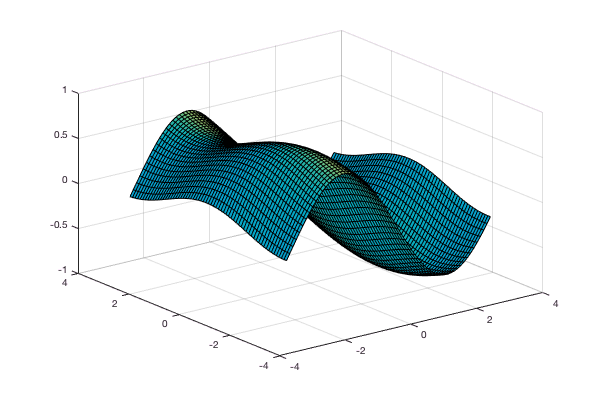


[Q2,Q3] = meshgrid(-pi:0.1:pi, -pi:0.1:pi);
for i=1:numcols(Q2),
    for j=1:numcols(Q3);
        M = p560.inertia([0 Q2(i,j) Q3(i,j) 0 0 0]);
        M11(i,j) = M(1,1);
        M12(i,j) = M(1,2);
    end
end
surfl (Q2, Q3, M11); surfl (Q2, Q3, M12);


max(M11(:)) / min(M11(:))

ans = 2.1558

## 9.2.3  Coriolis matrix

qd = [0 0 1 0 0 0];

C = p560.coriolis(qn, qd)

C =     0.3607   -0.0957   -0.0957    0.0005   -0.0004    0.0000
   -0.0000    0.3858    0.3858         0   -0.0000         0
         0         0   -0.0000    0.0000   -0.0009         0
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.0000    0.0009    0.0009         0         0         0
    0.0000         0         0    0.0000         0         0


C*qd'

ans =    -0.0957
    0.3858
   -0.0000
    0.0000
    0.0009
         0

## 9.2.5  Effect of payload

p560.payload(2.5, [0, 0, 0.1]);

M_loaded = p560.inertia(qn);

M_loaded ./ M

ans =     1.2893    2.3472   -1.5856  -76.8709   -0.0000   -0.0000
    2.3472    1.2856    3.2131    6.7027   97.9714    1.0000
   -1.5856    3.2131    1.6587   -2.0362   52.1246    1.0000
  -76.8709    6.7027   -2.0362    1.0652   22.7172    0.7071
   -0.0000   97.9714   52.1246   22.7172    1.1454    1.0000
   -0.0000    1.0000    1.0000    0.7071    1.0000    1.0000


p560.gravload(qn) ./ gravload

ans =     0.3737    1.5222    2.5416   18.7826   86.8056       NaN


p560.payload(0)

## 9.2.6  Base force

[Q,Wb] = p560.rne(qn, qz, qz);

Wb'

ans =          0   -0.0000  229.1616  -48.2699  -31.0852   -0.0000


sum([p560.links.m])

ans = 23.3600

## 9.2.7  Dynamic manipulability

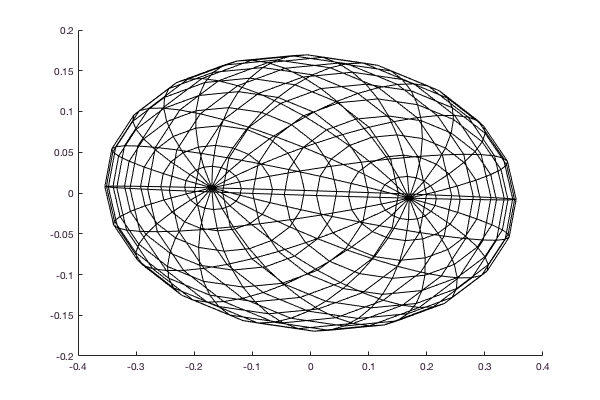

J = p560.jacob0(qn);
M = p560.inertia(qn);
Mx = (J * inv(M) * inv(M)' * J');

Mx = Mx(1:3, 1:3);

clf
plot_ellipse( Mx )


sqrt(eig(Mx))

ans =     0.4507
    0.1044
    0.1693


min(ans)/max(ans)

ans = 0.2315


p560.maniplty(qn, 'asada')

Manipulability: translation 0.206612, rotation 0.171619


## 9.3  Forward dynamics

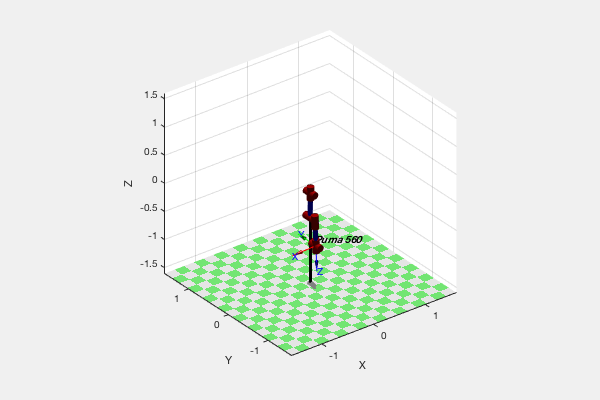

% qdd = p560.accel(q, qd, Q);

sl_ztorque

clf
r = sim('sl_ztorque');


t = r.find('tout');
q = r.find('yout');

clf
p560.plot(q)

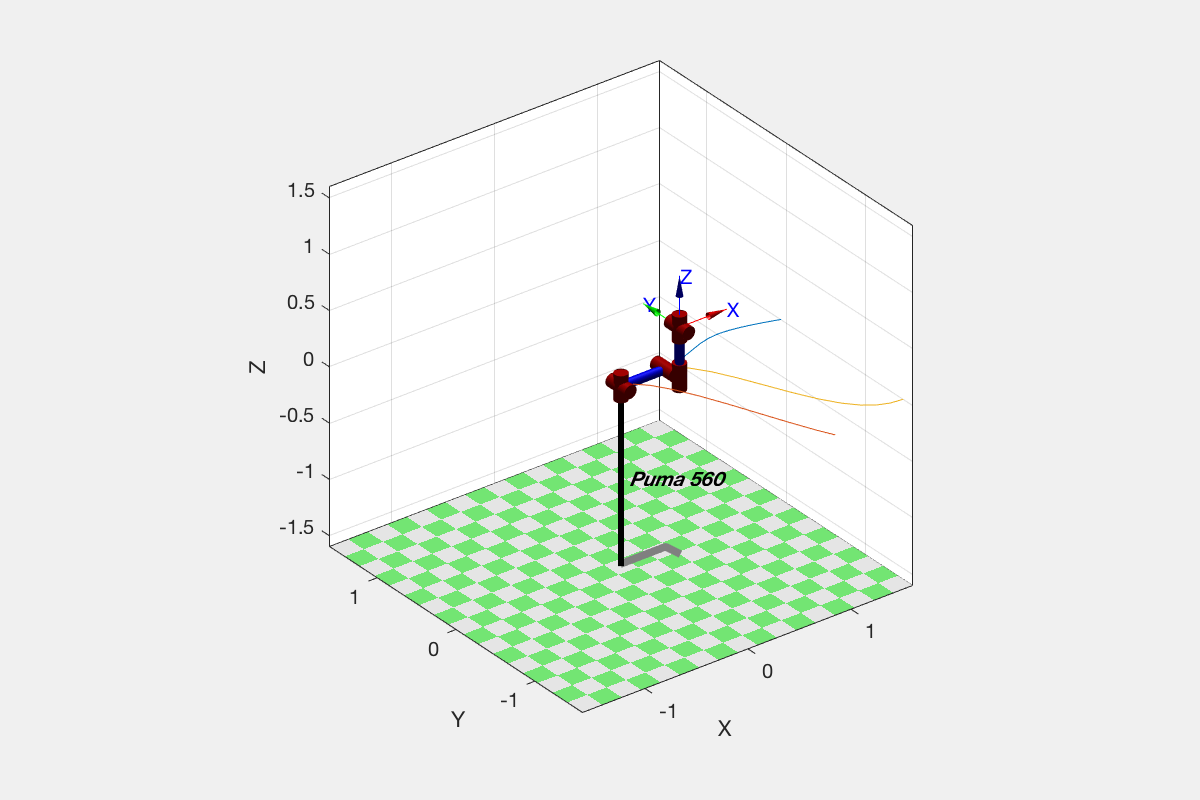


clf
plot(t, q(:,1:3))

## Warning box (page 272)

p560_nf = p560.nofriction();
p560_nf = p560.nofriction('all');

## 9.4  Rigid-body dynamics compensation

## 9.4.1  Feed forward control

mdl_puma560

sl_fforward

n = 6


r = sim('sl_fforward');

## 9.4.1  Computed torque control

mdl_puma560
sl_ctorque

r = sim('sl_ctorque');

t = r.find('tout');

## 9.4.3  Operational space control

sl_opspace

## 9.5.1  Series-elastic actuator

sl_sea

bdclose('all')